#### HW3 106010006 黃詩瑜 電機21 

8.

(a)

先求出 frequency response H(z):


$$\begin{array}{l}
y\left\lbrack n\right\rbrack =x\left\lbrack n-15\right\rbrack \\
\Rightarrow Y\left(Z\right)=Z^{-15} X\left(Z\right)\\
H\left(Z\right)=Z^{-15} 
\end{array}$$


plot phase using freqz:

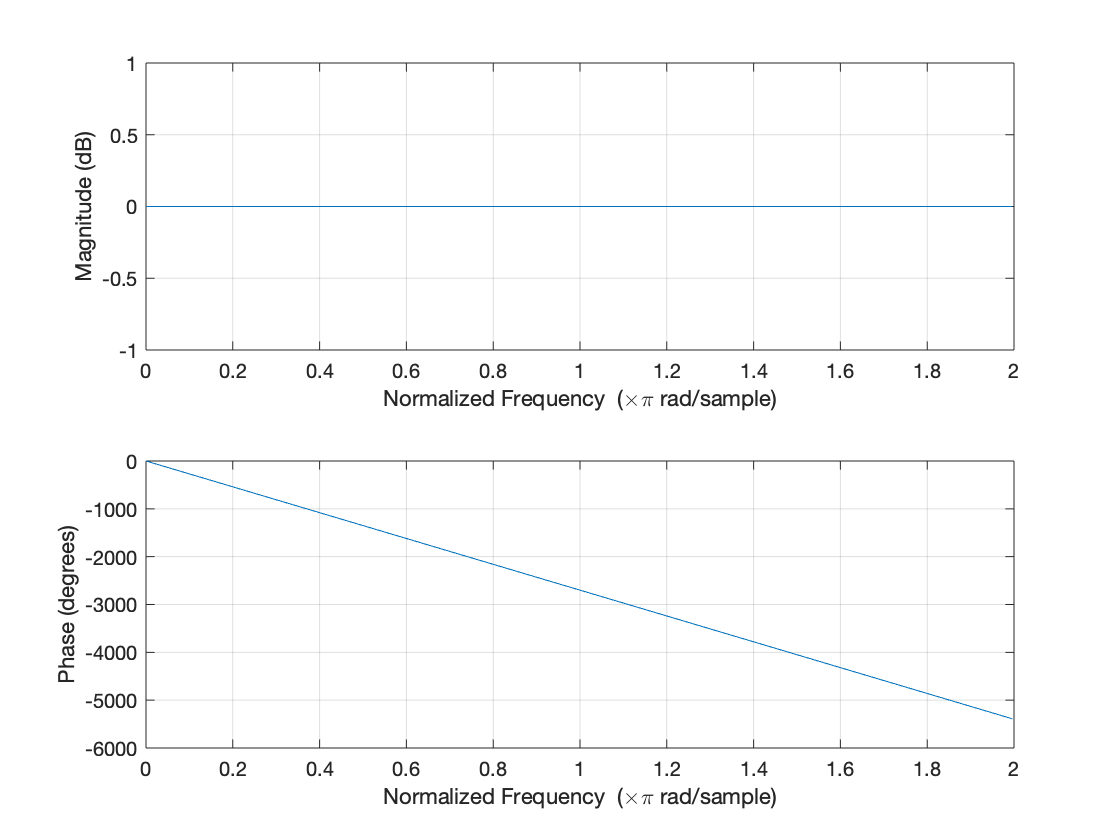

b=[0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1];
a=[1];
freqz(b,a,"whole")

using angle:

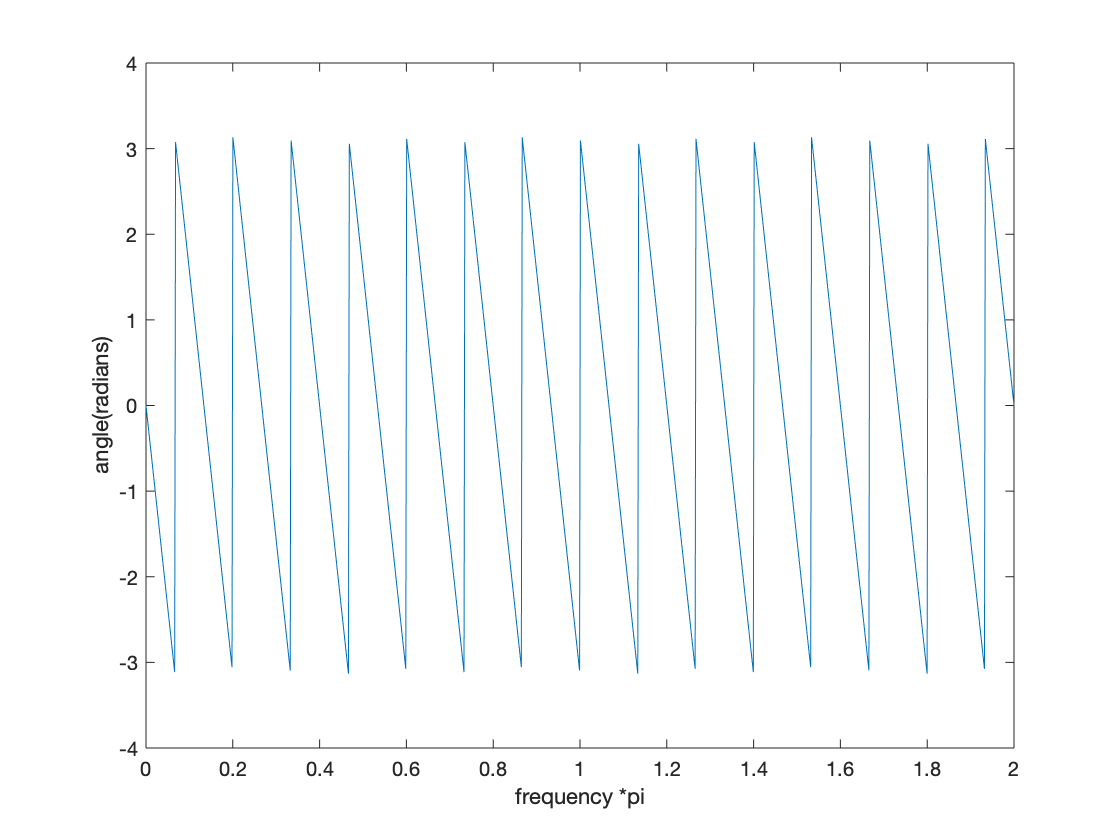

om=linspace(0,2*pi,1000);
b=[0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1];
a=[1];
H=freqz(b,a,om);
figure
plot(om/pi,angle(H));
xlabel('frequency *pi')
ylabel('angle(radians)')

using phasez:

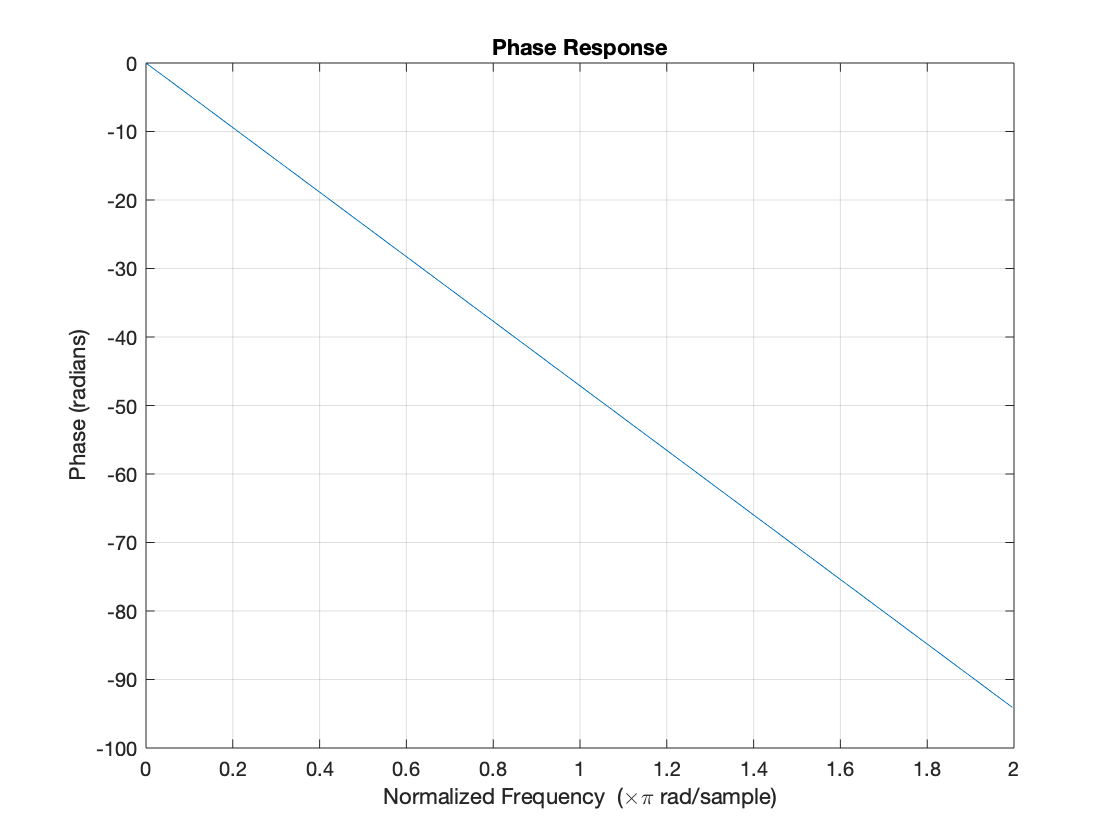

b=[0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1];
a=[1];
phasez(b,a,"whole")

由上圖可看出angle function畫出的是principal phase ，而 phasez function則為continuous phase

using unwrap:

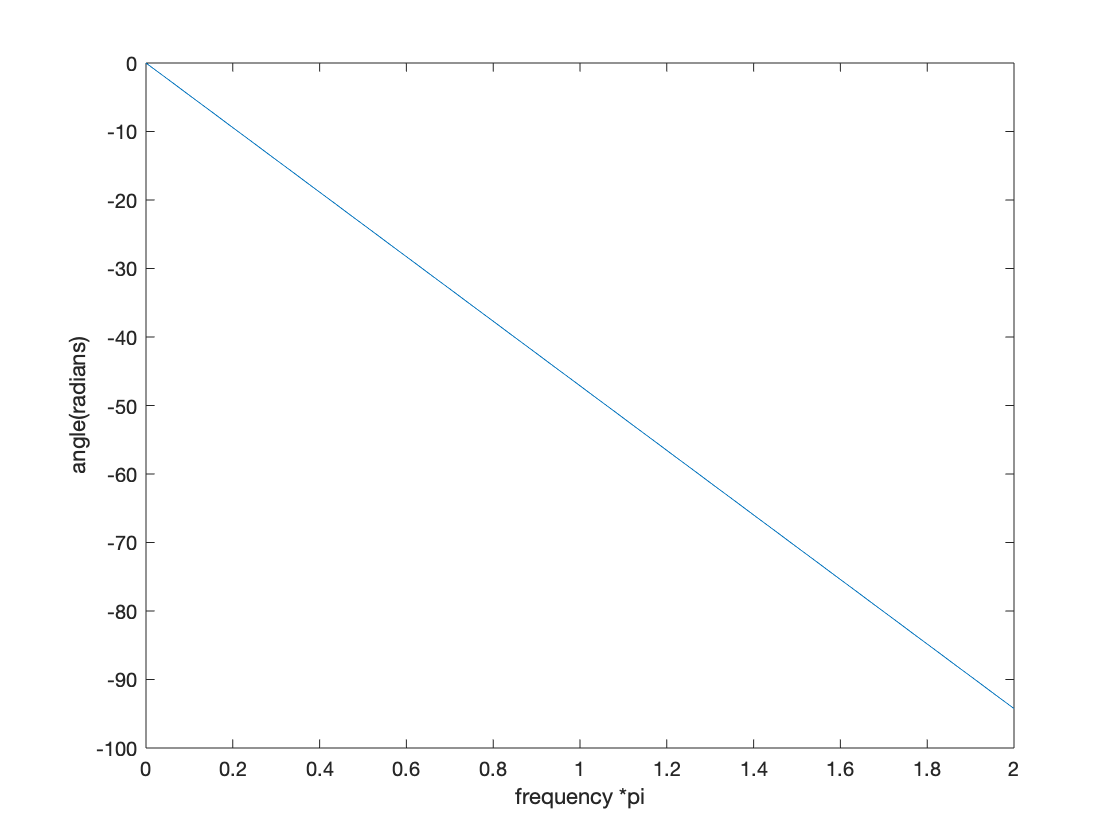

om=linspace(0,2*pi,1000);
b=[0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1];
a=[1];
H=freqz(b,a,om);
p=angle(H);
Q = unwrap(p);
figure
plot(om/pi,Q);
xlabel('frequency *pi')
ylabel('angle(radians)')

using phasedelay:

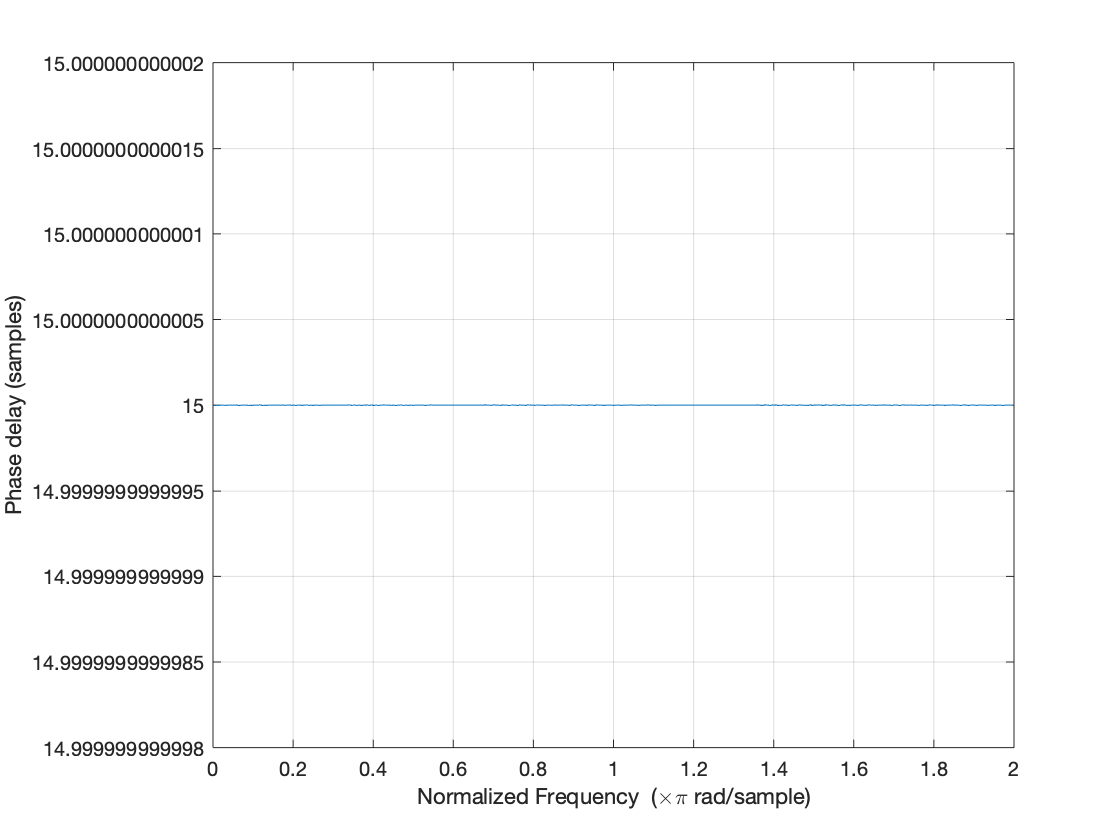

b=[0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1];
a=[1];
phasedelay(b,a,"whole")

(b)

plot phase using freqz:

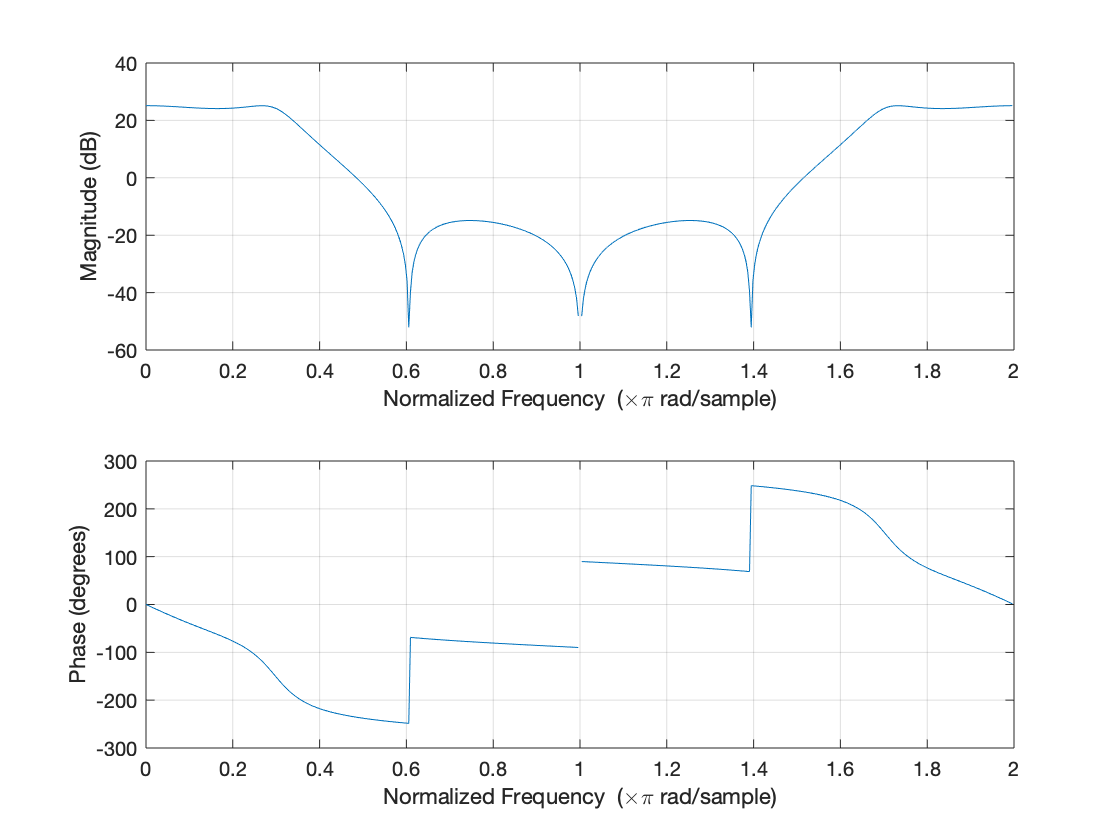

b=[1 1.655 1.655 1];
a=[1 -1.57 1.264 -0.4];
freqz(b,a,"whole")

using angle:

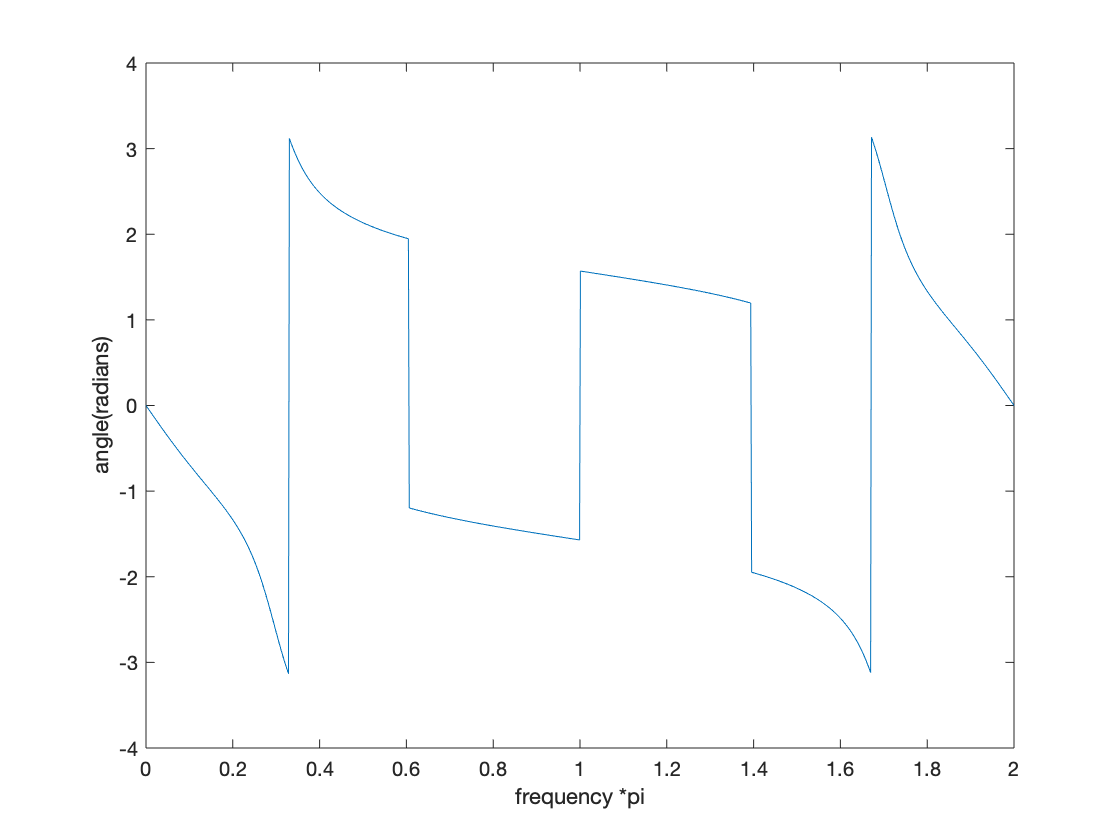

om=linspace(0,2*pi,1000);
b=[1 1.655 1.655 1];
a=[1 -1.57 1.264 -0.4];
H=freqz(b,a,om);
figure
plot(om/pi,angle(H));
xlabel('frequency *pi')
ylabel('angle(radians)')

using phasez:

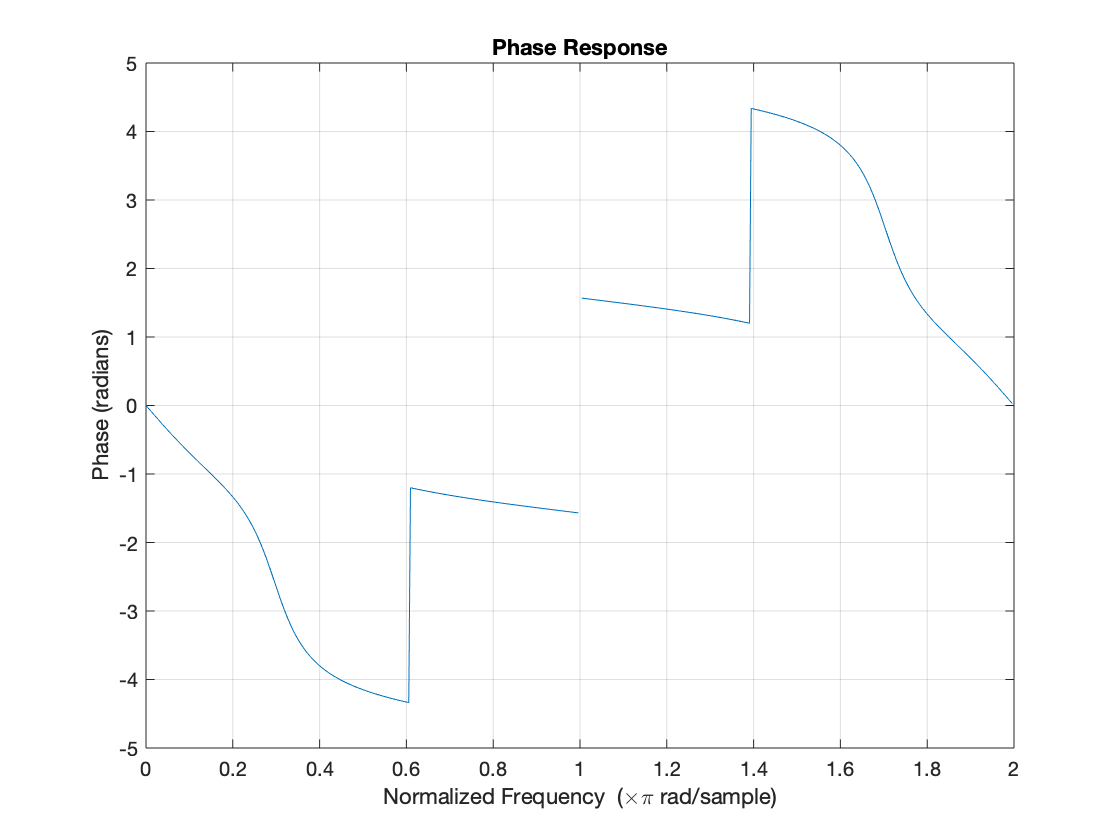

b=[1 1.655 1.655 1];
a=[1 -1.57 1.264 -0.4];
phasez(b,a,"whole")

using unwrap:

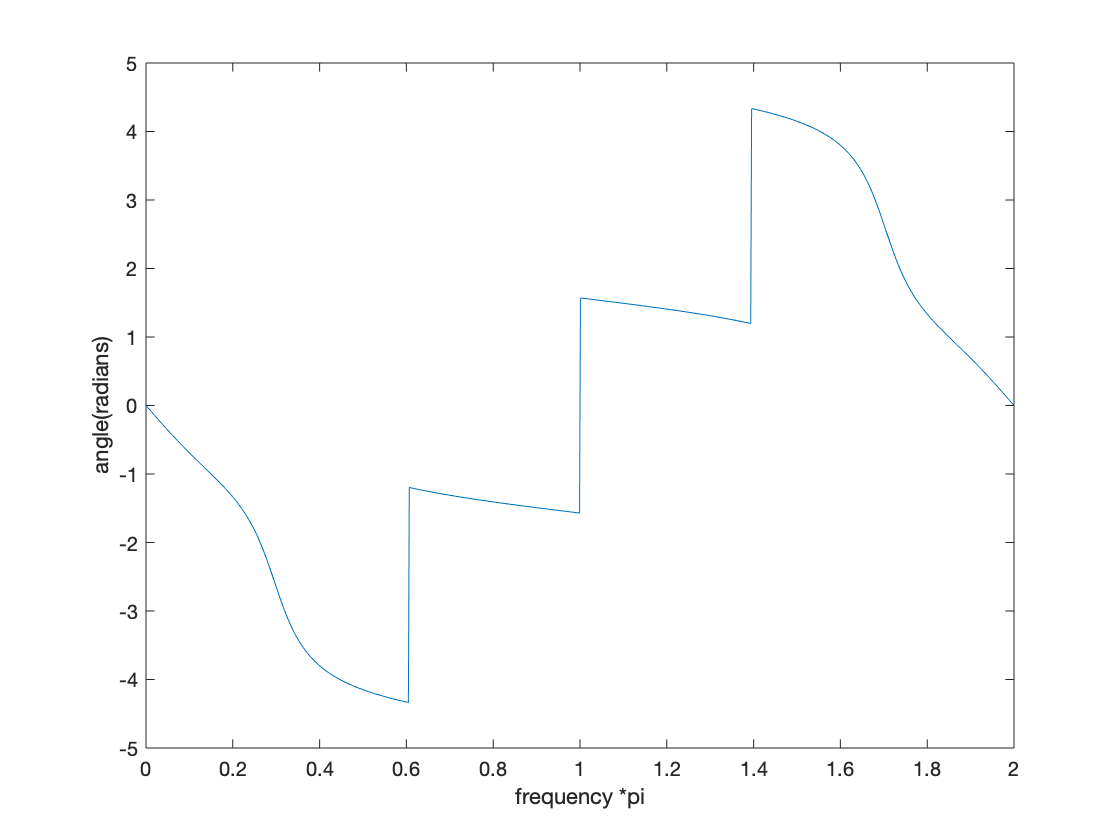

om=linspace(0,2*pi,1000);
b=[1 1.655 1.655 1];
a=[1 -1.57 1.264 -0.4];
H=freqz(b,a,om);
p=angle(H);
Q = unwrap(p);
figure
plot(om/pi,Q);
xlabel('frequency *pi')
ylabel('angle(radians)')

using phasedelay:

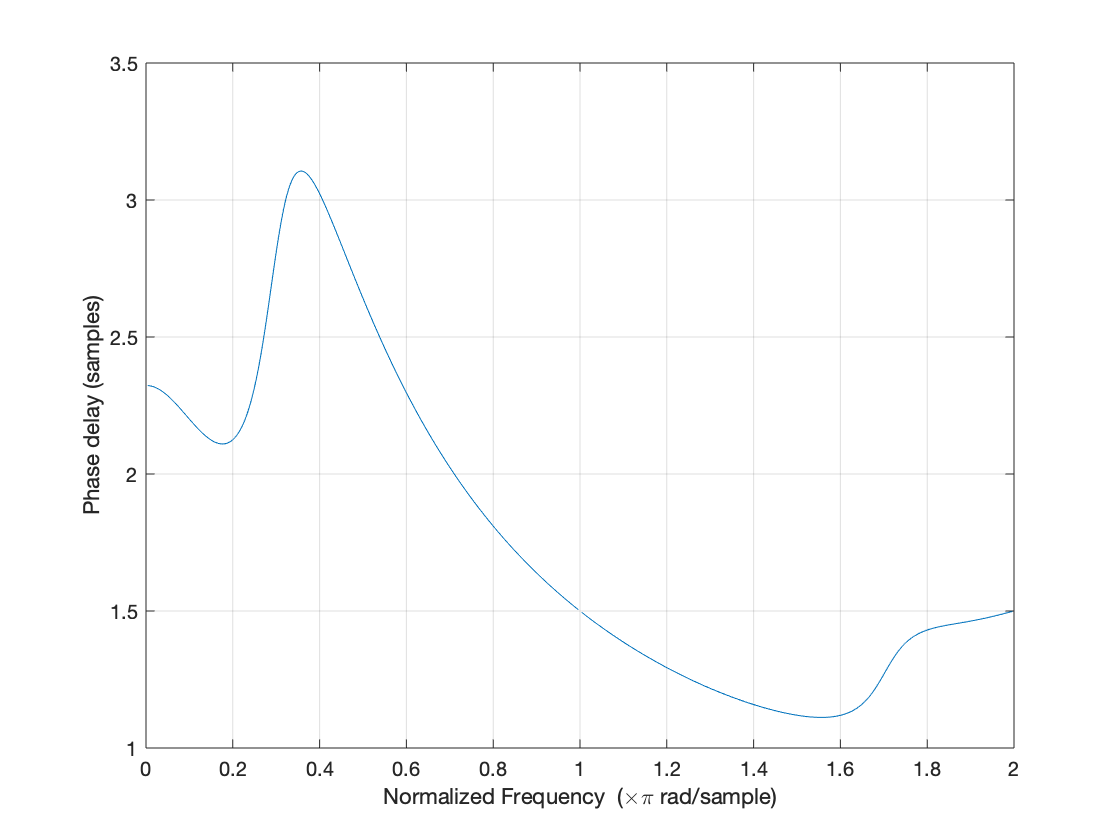

b=[1 1.655 1.655 1];
a=[1 -1.57 1.264 -0.4];
phasedelay(b,a,"whole")

9.

(a)

h[n]=[1 -2 3 -4 0 4 -3 2 -1]

n>0，因此可使用freqz畫出magnitude and phase response:

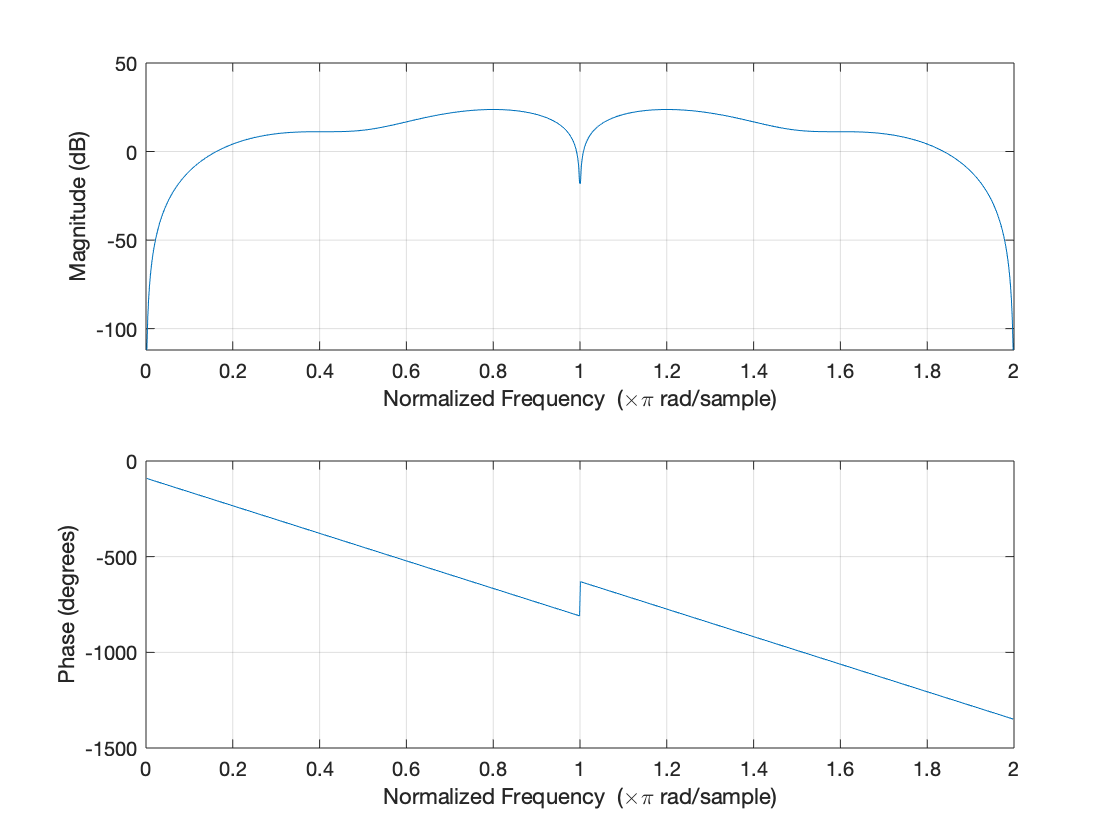

n=(0:1:8);
h=[1 -2 3 -4 0 4 -3 2 -1];
om=linspace(0,2*pi,1000);
freqz(h,1,om);

group delay:

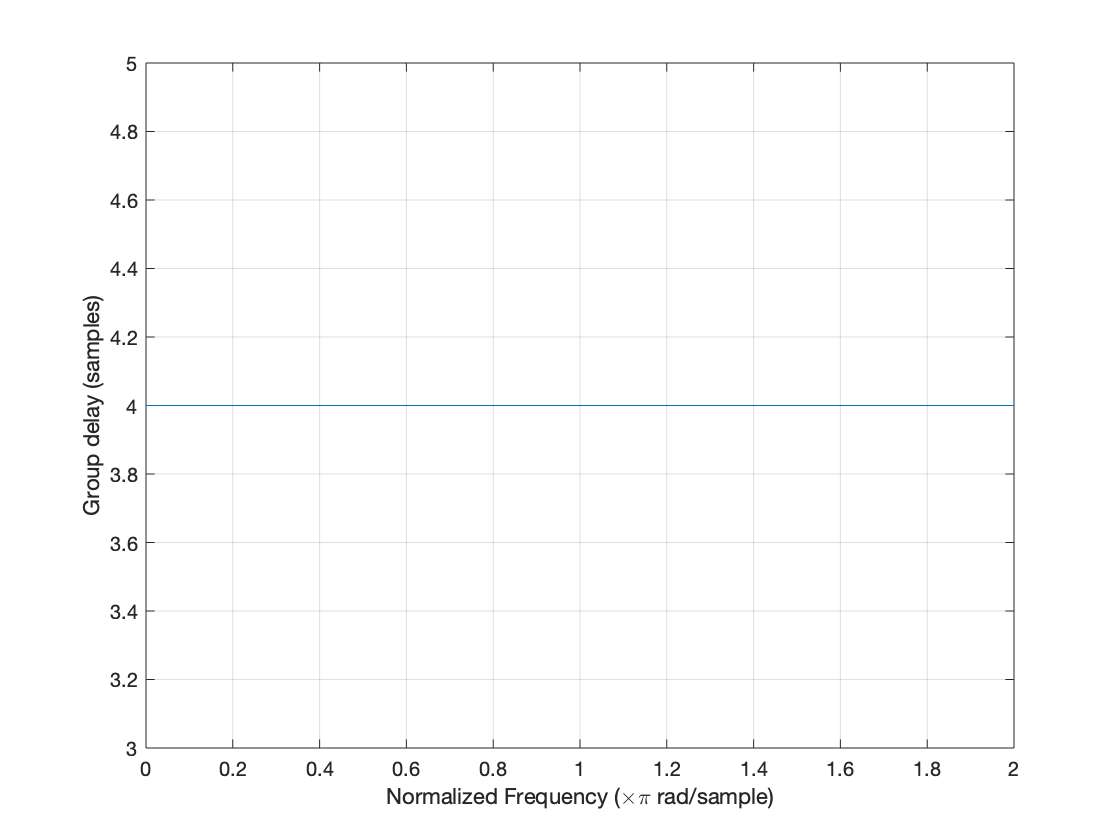

n=(0:1:8);
h=[1 -2 3 -4 0 4 -3 2 -1];
om=linspace(0,2*pi,1000);
grpdelay(h,1,om)

(b)

先求出 frequency response H(z):


$$\begin{array}{l}
y\left\lbrack n\right\rbrack =10x\left\lbrack n-10\right\rbrack \\
\Rightarrow Y\left(Z\right)=10Z^{-10} X\left(Z\right)\\
\Rightarrow H\left(Z\right)=10Z^{-10} 
\end{array}$$


用freqz畫出magnitude and phase response:

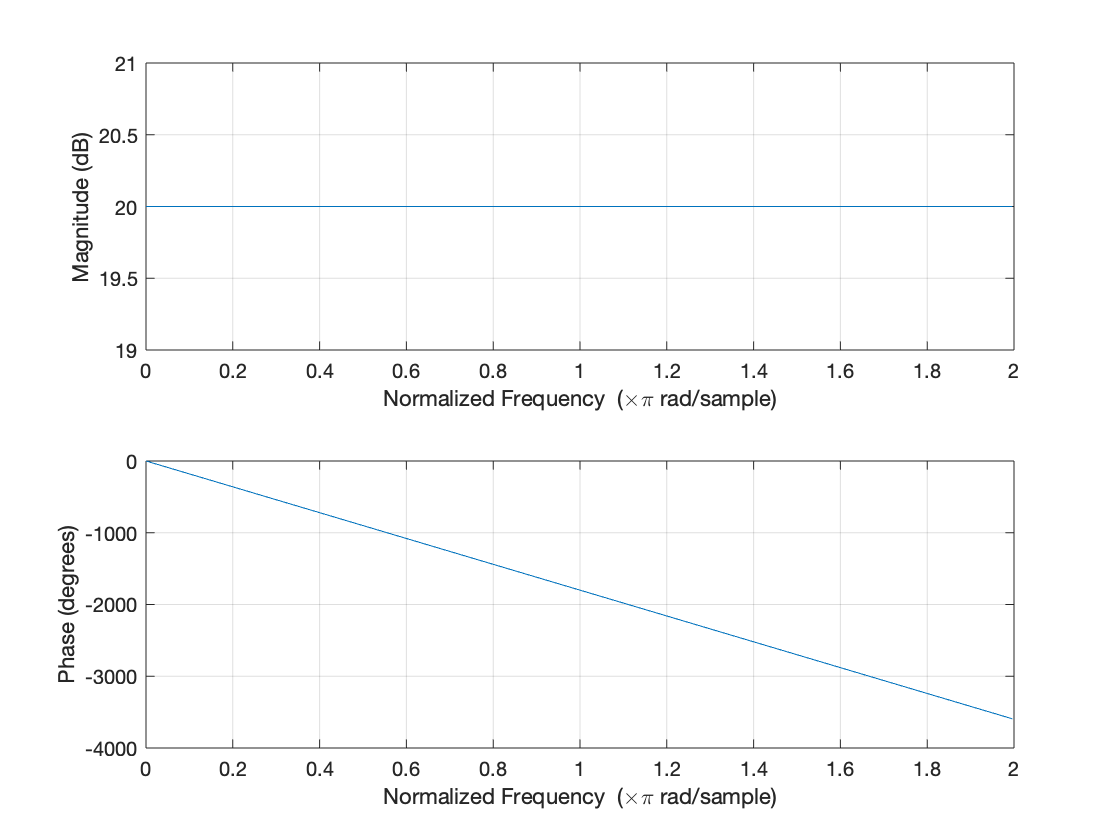

b=[0 0 0 0 0 0 0 0 0 0 10];
a=[1];
freqz(b,a,"whole")

group delay:

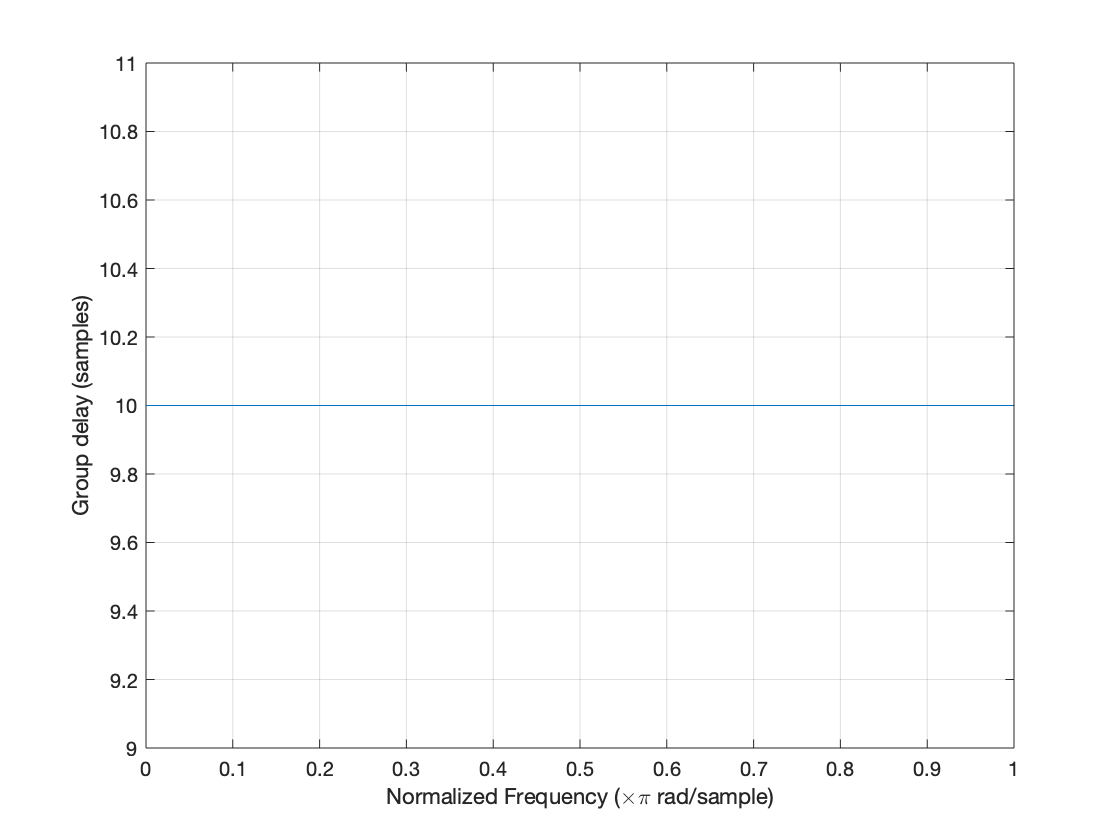

b=[0 0 0 0 0 0 0 0 0 0 10];
a=[1];
grpdelay(b,a,1000)

10.

(a)

 先畫出原本pole和zero的位置


$$H\left(Z\right)=\frac{1+2Z^{-1} +0\ldotp 75Z^{-2} }{1-0\ldotp 5Z^{-1} }$$


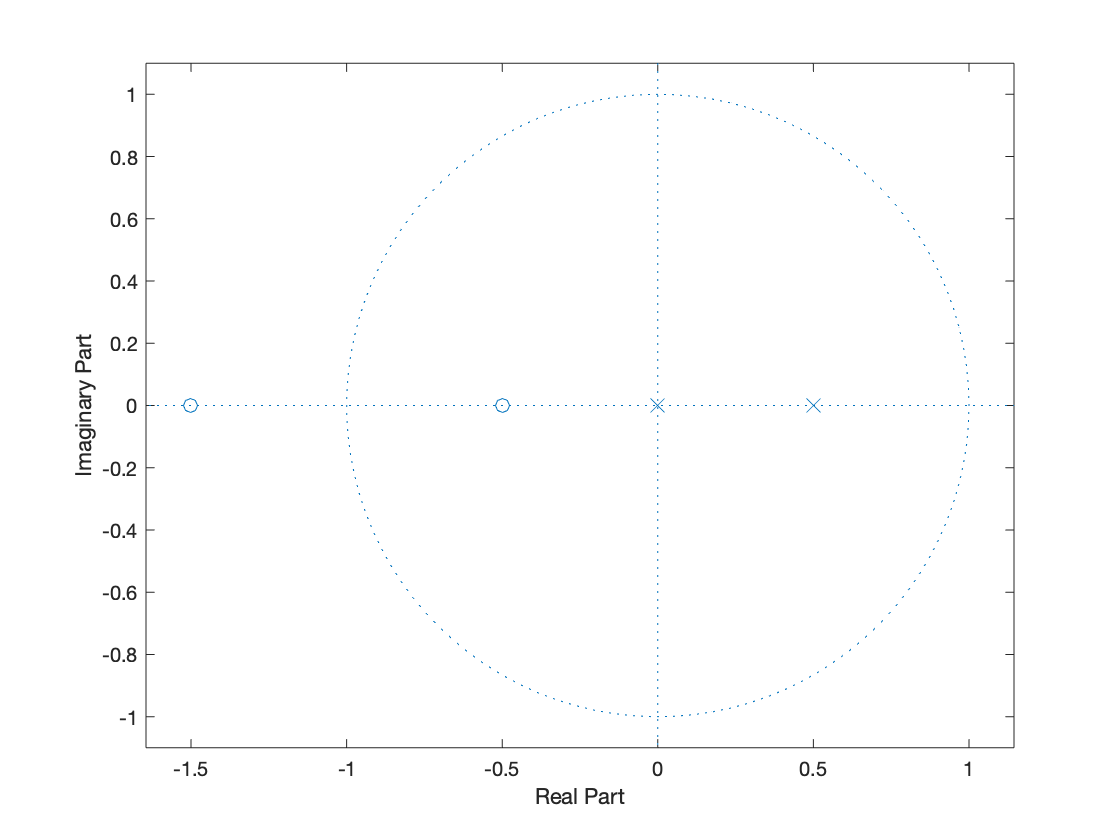

b=[1 2 0.75];
a=[1 -0.5];
zplane(b,a)

有個 zero=-1.5 在unit circle外，使用polystab：

b1,a1為原本的coefiicient，經過polystab後為b2,a2

b1=[1 2 0.75];
a1=[1 -0.5];
b2=polystab(b1)

b2 =     1.0000    1.1667    0.3333


a2=polystab(a1)

a2 =     1.0000   -0.5000


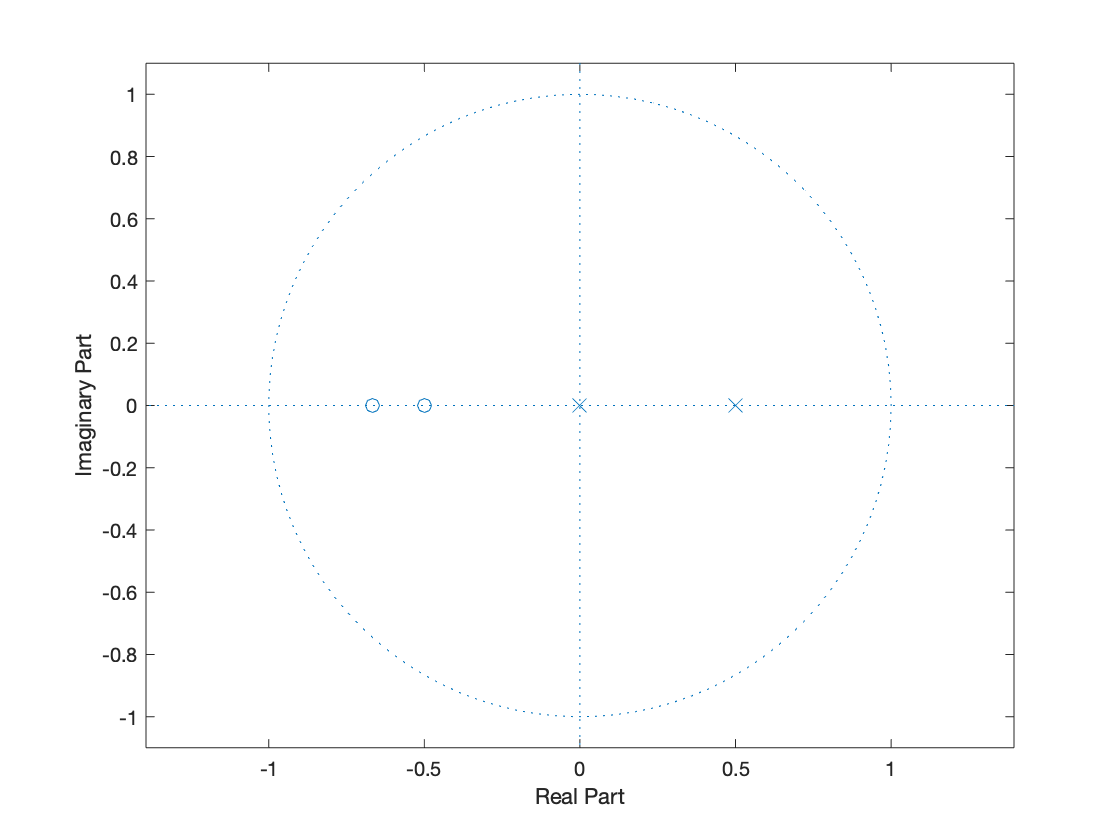

zplane(b2,a2)

由上圖可看出zero和pole都在unit circle內，

經轉換過的system為minimum phase Hmin


$$H_{\min } =\frac{1+1\ldotp 1667Z^{-1} +0\ldotp 3333Z^{-2} }{1-0\ldotp 5Z^{-1} }$$


將Hmin的zero轉換到unit cirlce外，就會產生maximum phase systems


$$H_{\max } =\frac{0\ldotp 3333+1\ldotp 1667Z^{-1} +Z^{-2} }{1-0\ldotp 5Z^{-1} }$$


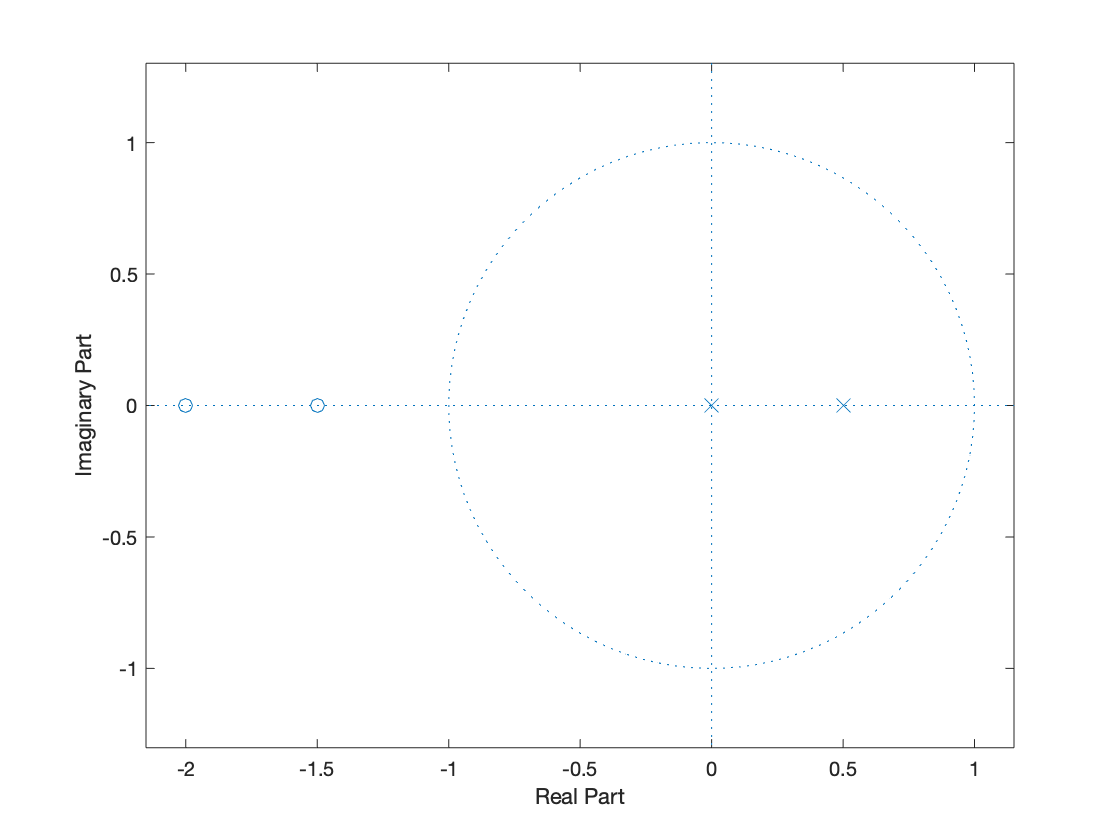

bmax=[0.3333 1.1667 1];
amax=[1 -0.5];
zplane(bmax,amax)

上圖可看出zero都在unit circle外

畫出Hmin和Hmax的phase做比較:

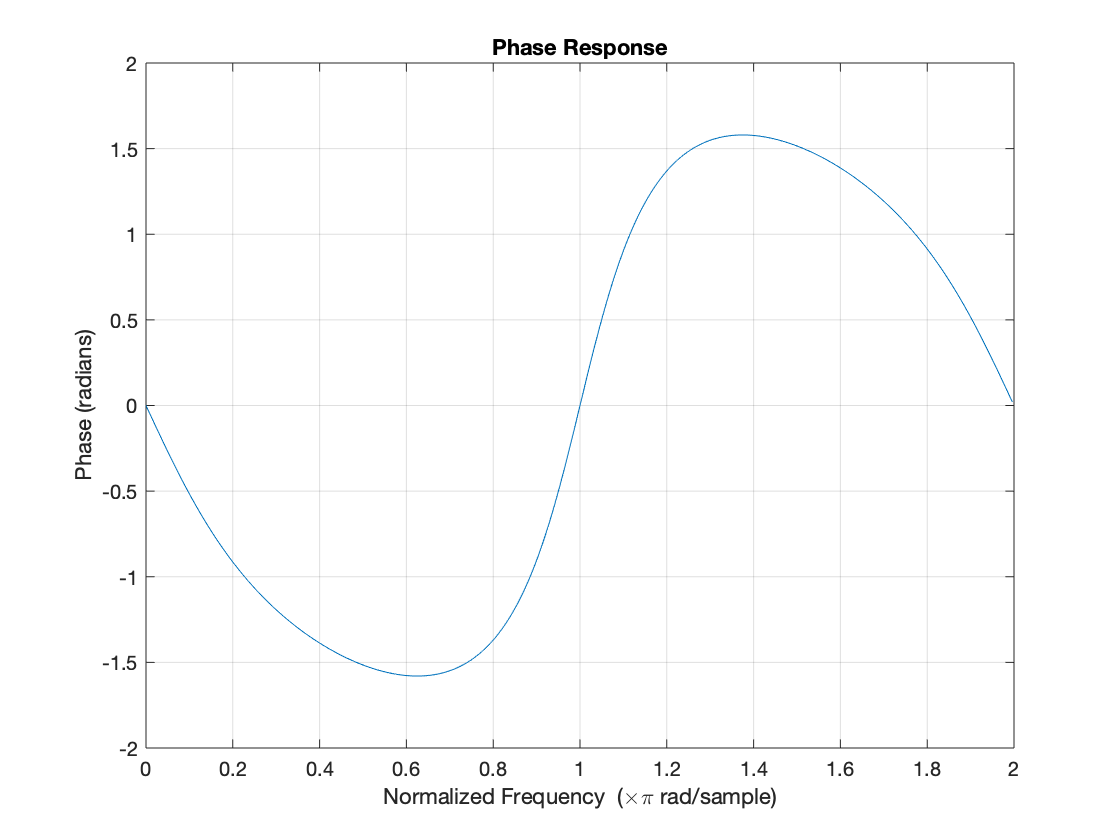

bmin=[1 1.1667 0.3333];
amin=[1 -0.5];
phasez(bmin,amin,"whole");

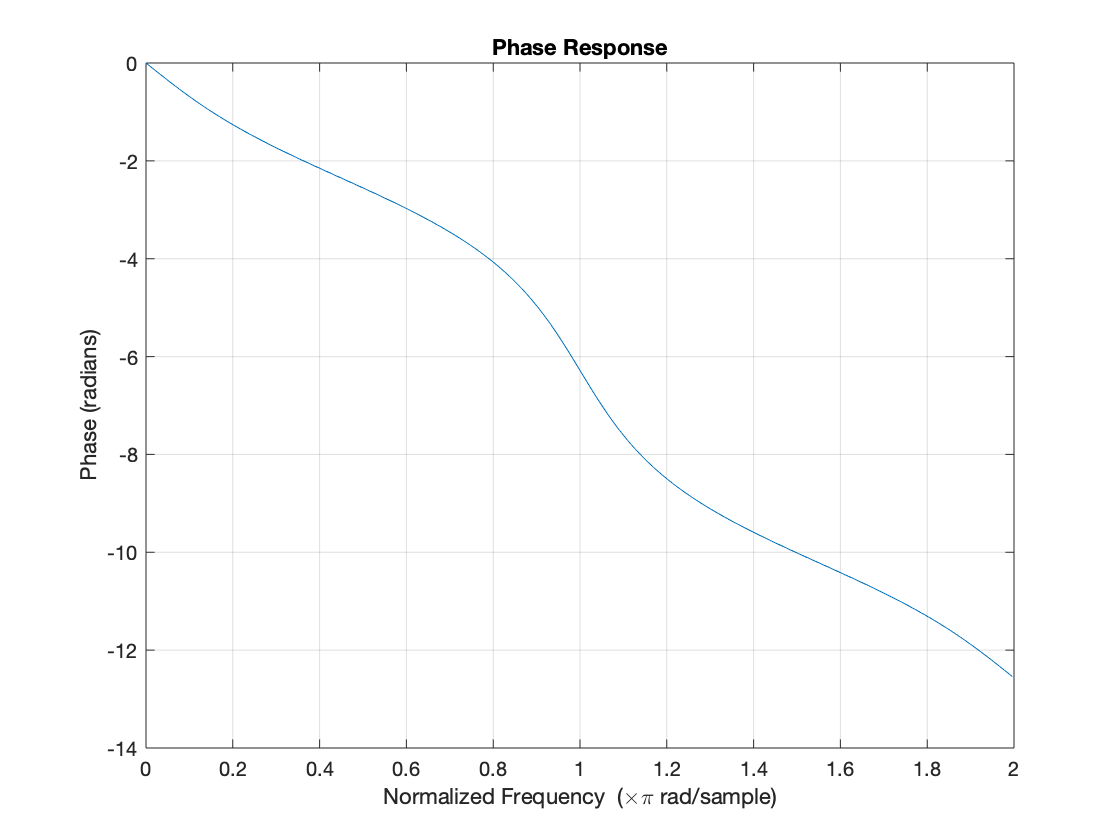

bmax=[0.3333 1.1667 1];
amax=[1 -0.5];
phasez(bmax,amax,"whole");

檢查minimun和maximum phase 是否正確

min_flag = isminphase(bmin,amin)

min_flag = logical
   1


max_flag = ismaxphase(bmax,amax)

max_flag = logical
   1


經檢查後為正確

(b)

先畫出原本pole和zero的位置


$$H\left(Z\right)=\frac{1-2\ldotp 4142Z^{-1} +2\ldotp 4142Z^{-2} -Z^{-3} }{1-1\ldotp 8Z^{-1} +1\ldotp 62Z^{-2} +0\ldotp 729Z^{-3} }$$


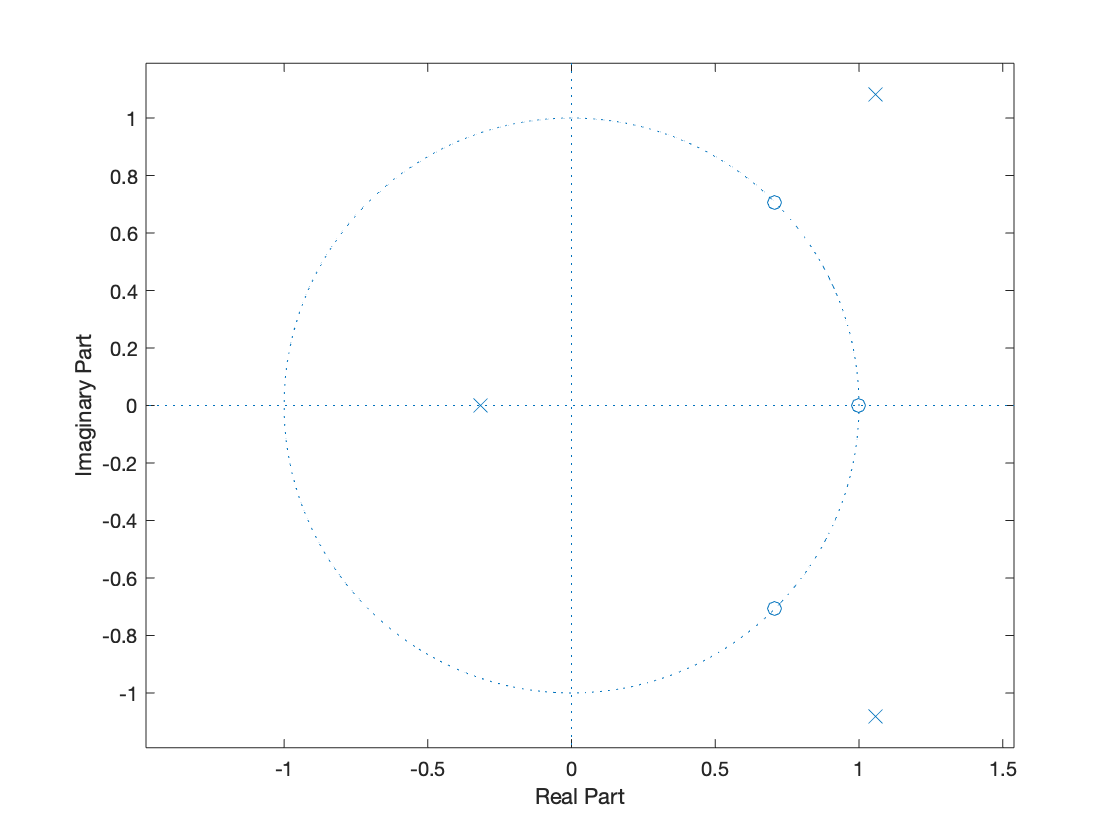

b=[1 -2.4142 2.4142 -1];
a=[1 -1.8 1.62 0.729];
zplane(b,a)

有2個 pole在unit circle外，使用polystab：

b1,a1為原本的coefiicient，經過polystab後為b2,a2

b1=[1 -2.4142 2.4142 -1];
a1=[1 -1.8 1.62 0.729];
b2=polystab(b1)

b2 =     1.0000   -2.4142    2.4142   -1.0000


a2=polystab(a1)

a2 =     1.0000   -0.6056    0.1425    0.1386


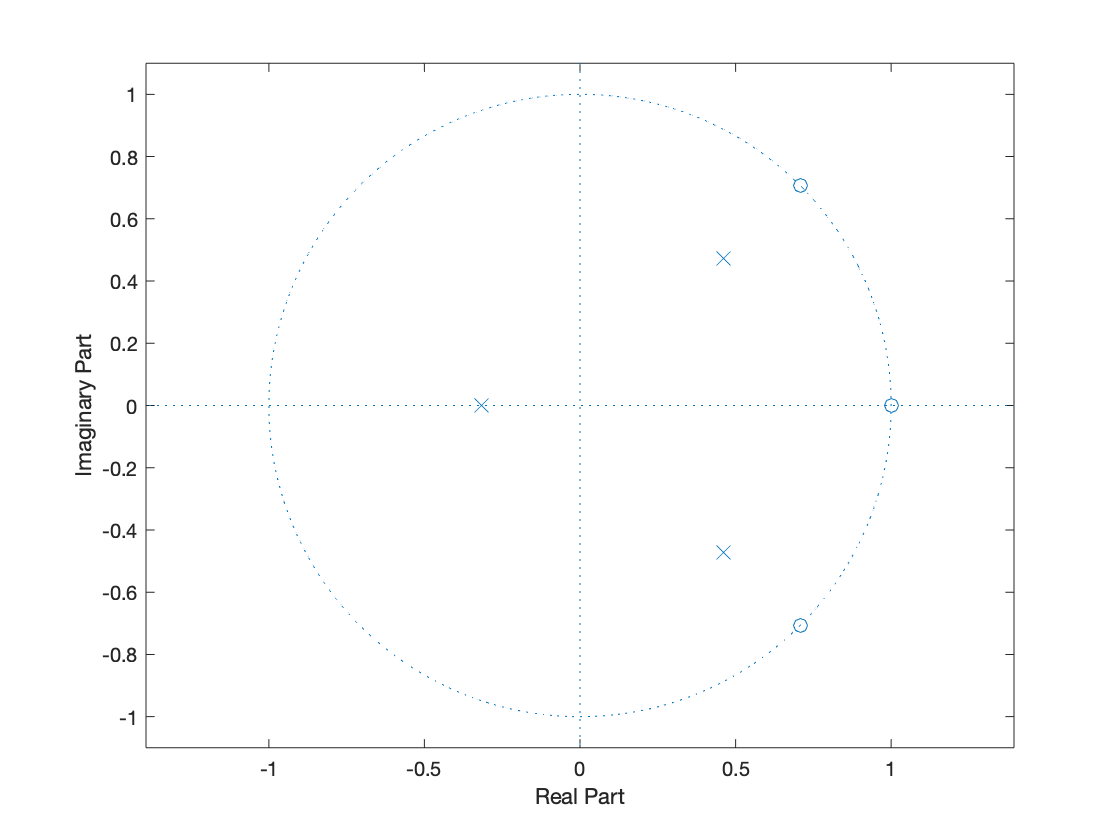

zplane(b2,a2)

由上圖可看出zero和pole都在unit circle內，

經轉換過的system為minimum phase Hmin


$$H_{\min } \left(Z\right)=\frac{1-2\ldotp 4142Z^{-1} +2\ldotp 4142Z^{-2} -Z^{-3} }{1-0\ldotp 6056Z^{-1} +0\ldotp 1425Z^{-2} +0\ldotp 1386Z^{-3} }$$


因為zeros都在unit circlr上，所以產生的maximum phase systems，zero位置不變


$$H_{\max } \left(Z\right)=\frac{-1+2\ldotp 4142Z^{-1} -2\ldotp 4142Z^{-2} +Z^{-3} }{1-0\ldotp 6056Z^{-1} +0\ldotp 1425Z^{-2} +{0\ldotp 1386Z}^{-3} }$$


bmax=[-1 2.4142 -2.4142 1];
amax=[1 -0.6056 0.1425 0.1386];
zplane(bmax,amax)

畫出Hmin和Hmax的phase做比較:

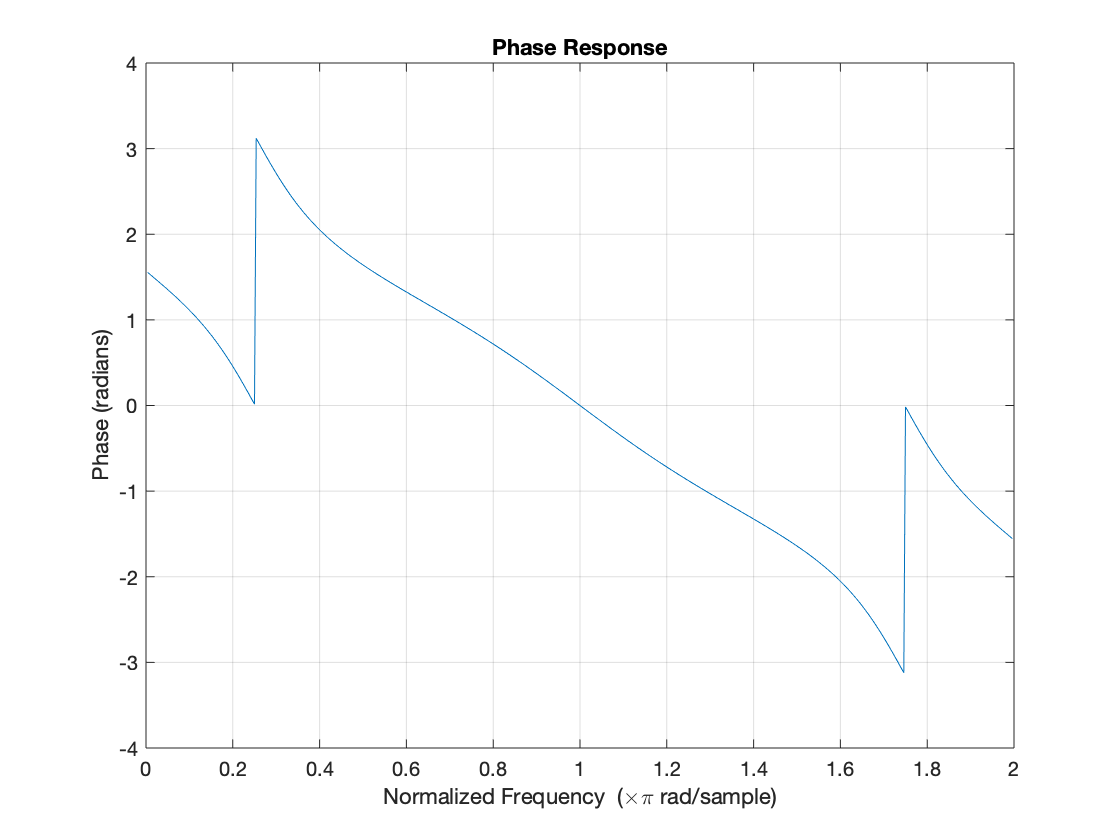

bmin=[1 -2.4142 2.4142 -1];
amin=[1 -0.6056 0.1425 0.1386];
phasez(bmin,amin,"whole");

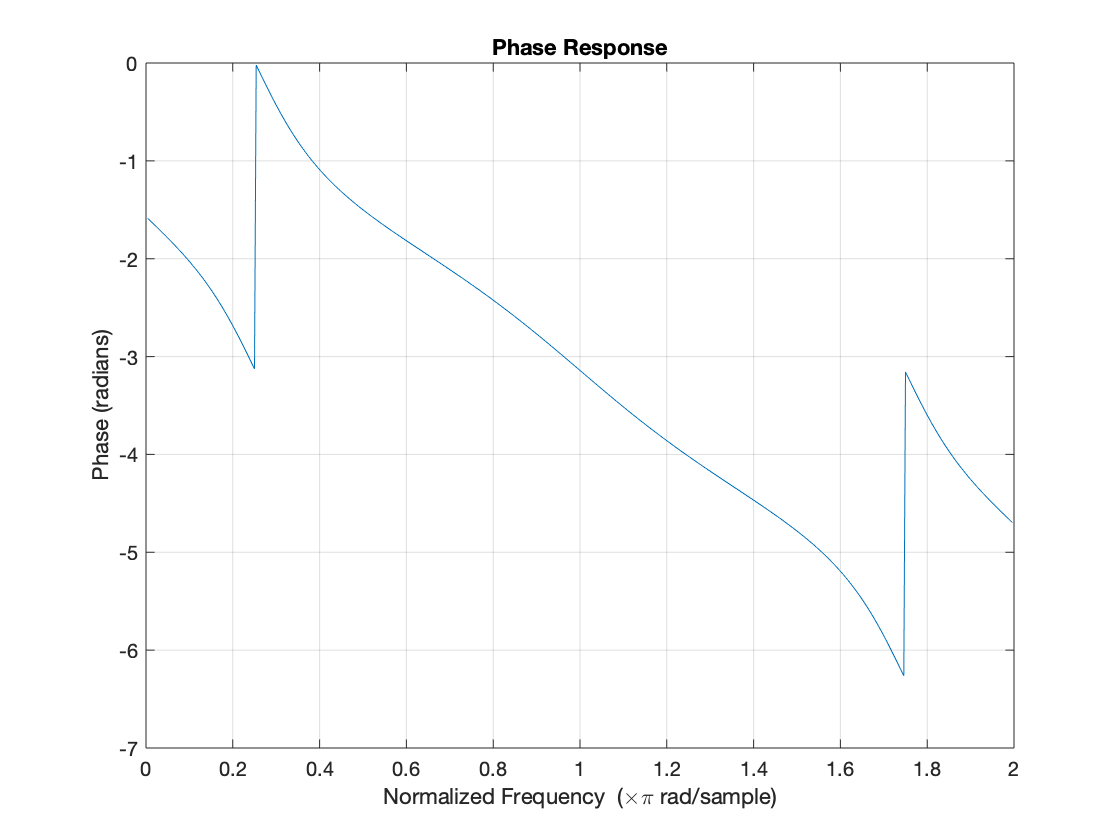

bmax=[-1 2.4142 -2.4142 1];
amax=[1 -0.6056 0.1425 0.1386];
phasez(bmax,amax,"whole");

檢查minimun和maximum phase 是否正確

min_flag = isminphase(bmin,amin)

min_flag = logical
   1


max_flag = ismaxphase(bmax,amax)

max_flag = logical
   1


經檢查後為正確

11.

 先算出$X_c \left(j\omega \right)$


$$\begin{array}{l}
x\left(t\right)=5\cos \left(200\pi t+6\pi \right)+4\sin \left(300\pi t\right)\\
=5\cos \left(200\pi t\right)+4\sin \left(300\pi t\right)\\
\Rightarrow X_c \left(\omega \right)=5\pi \left\lbrack \delta \left(\omega -200\pi \right)+\delta \left(\omega +200\pi \right)\right\rbrack +4i\pi \left\lbrack \delta \left(\omega +300\pi \right)-\delta \left(\omega -300\pi \right)\right\rbrack 
\end{array}$$


再代入公式

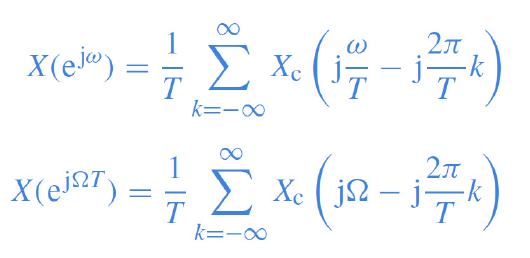


$$\Rightarrow X\left(e^{j\omega } \right)=F_s \sum_{k=-\infty }^{\infty } \left\lbrack 5\pi \left\lbrack \delta \left(\omega F_s -2\pi F_s k-200\pi \right)+\delta \left(\omega F_s -2\pi F_s k+200\pi \right)\right\rbrack +4i\pi \left\lbrack \delta \left(\omega F_s -2\pi F_s k+300\pi \right)-\delta \left(\omega F_s -2\pi F_s k-300\pi \right)\right\rbrack \right\rbrack$$


when Fs=1000Hz


$$X\left(e^{j\omega } \right)=1000\sum_{k=-\infty }^{\infty } \left\lbrack 5\pi \left\lbrack \delta \left(1000\omega -2000\pi k-200\pi \right)+\delta \left(1000\omega -2000\pi k+200\pi \right)\right\rbrack +4i\pi \left\lbrack \delta \left(1000\omega -2000\pi k+300\pi \right)-\delta \left(1000\omega -2000\pi k-300\pi \right)\right\rbrack \right\rbrack$$


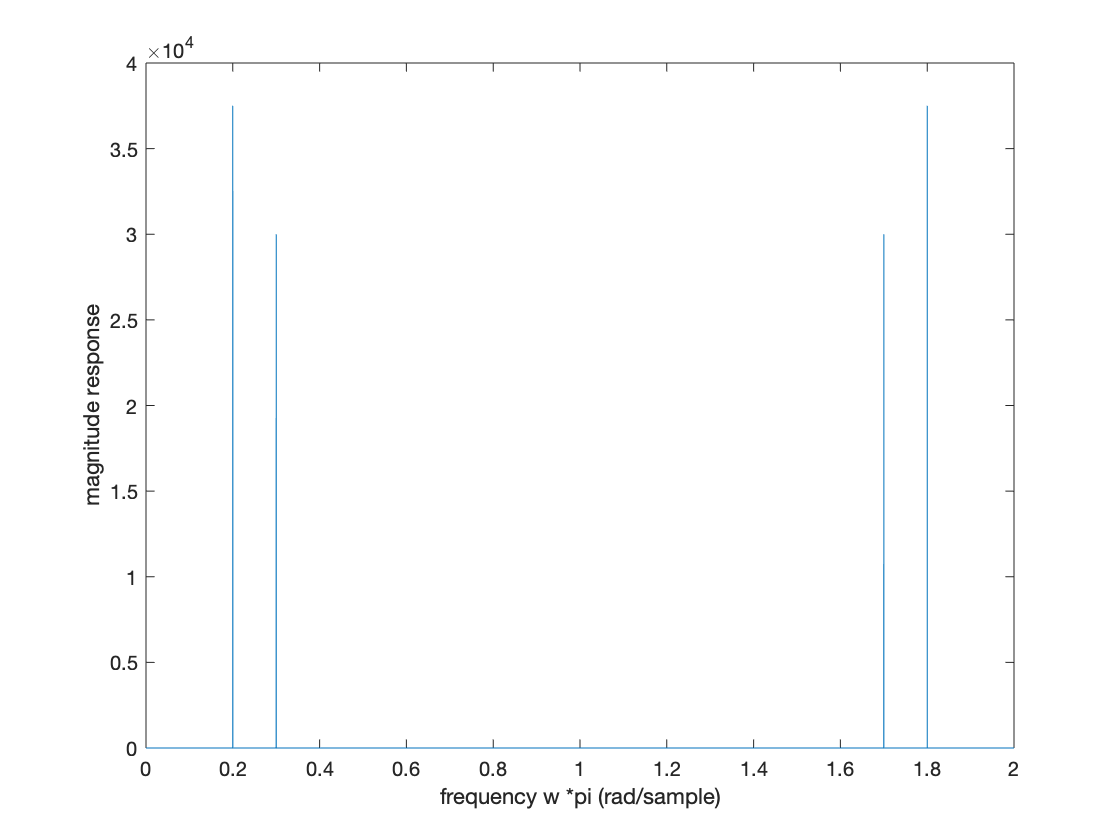

Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 15000;             % Length of signal
t = (0:L-1)*T;        % Time vector
x=5*cos(200*pi*t+6*pi) + 4*sin(300*pi*t);
Y = fft(x);
f = Fs*(0:(L-1))/L;
figure
om=linspace(0,2*pi,15000);
plot(om/pi,abs(Y))
xlabel("frequency w *pi (rad/sample)")
ylabel("magnitude response")

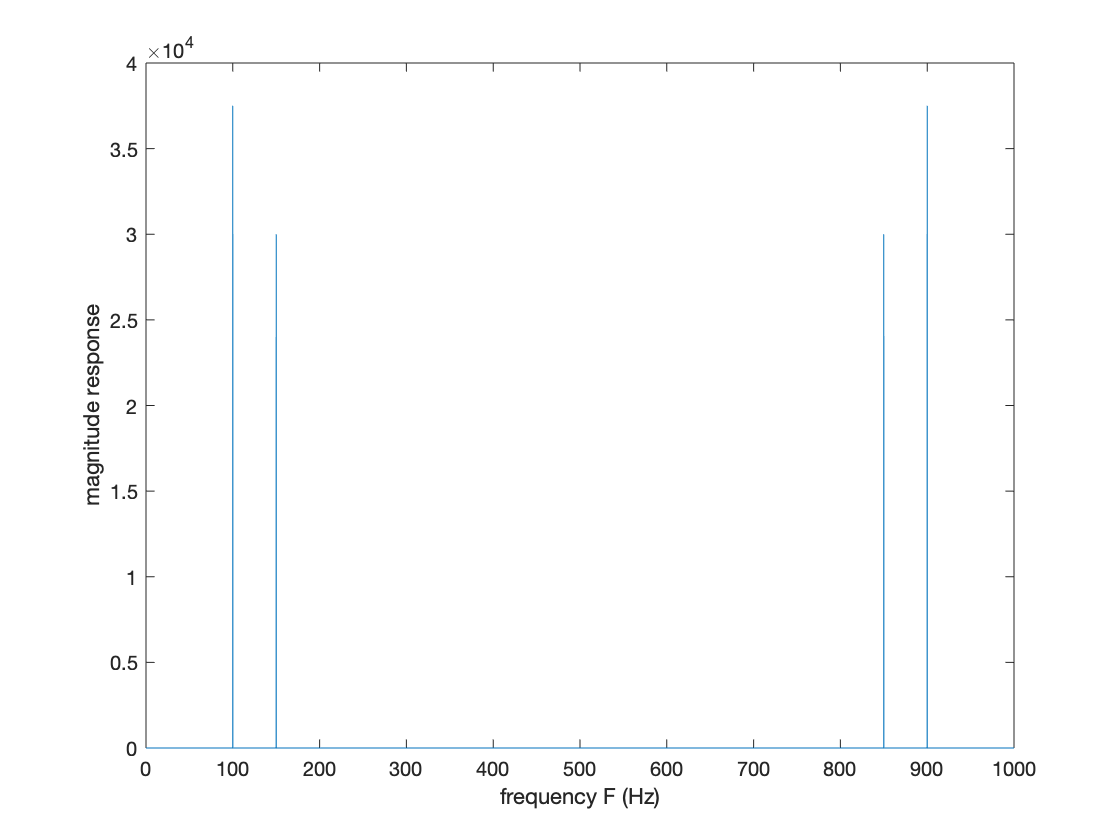

plot(f,abs(Y))
xlabel("frequency F (Hz)")
ylabel("magnitude response")

the original signal xc(t) can be recovered from x[n]，


$$\begin{array}{l}
F_s =1000\;,\;\Omega_s =2000\pi \;,\Omega_H =300\pi \\
\Rightarrow \Omega_s >{2\Omega }_H 
\end{array}$$


There is no aliasing.

(b)

when Fs=500Hz


$$X\left(e^{j\omega } \right)=500\sum_{k=-\infty }^{\infty } \left\lbrack 5\pi \left\lbrack \delta \left(500\omega -1000\pi k-200\pi \right)+\delta \left(500\omega -1000\pi k+200\pi \right)\right\rbrack +4i\pi \left\lbrack \delta \left(500\omega -1000\pi k+300\pi \right)-\delta \left(500\omega -1000\pi k-300\pi \right)\right\rbrack \right\rbrack$$


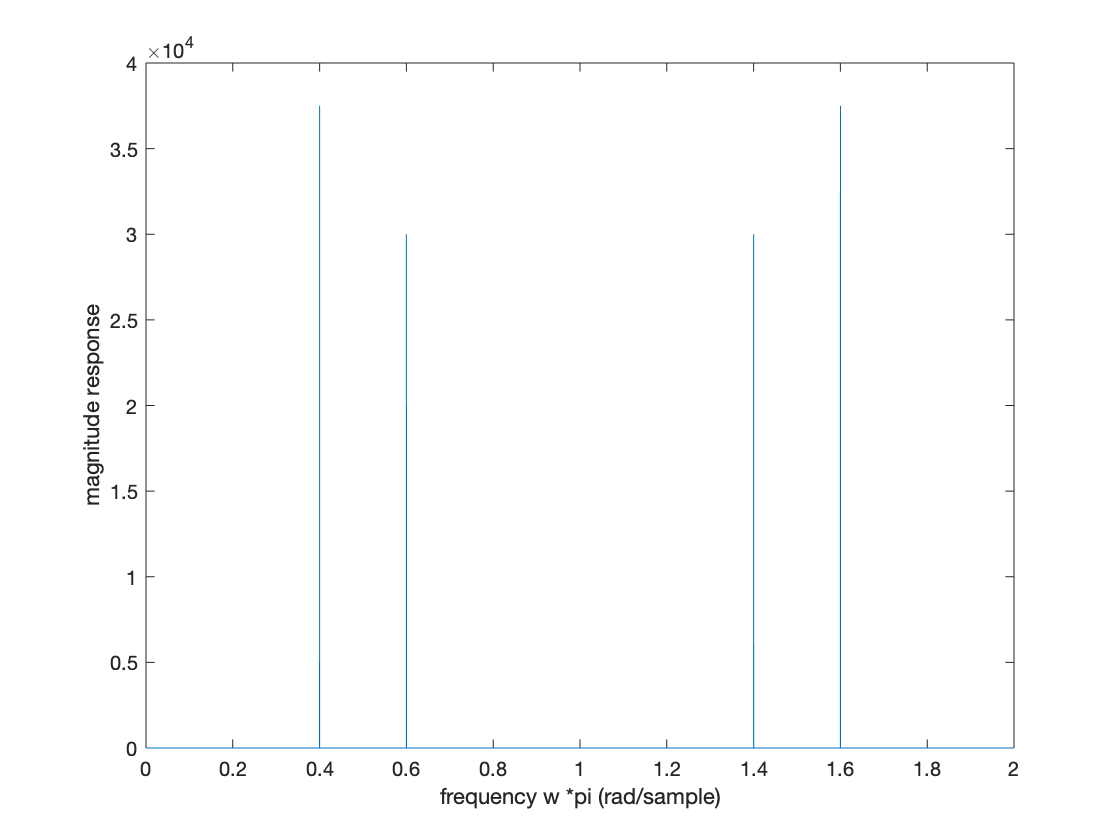

Fs = 500;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 15000;             % Length of signal
t = (0:L-1)*T;        % Time vector
x=5*cos(200*pi*t+6*pi) + 4*sin(300*pi*t);
Y = fft(x);
f = Fs*(0:(L-1))/L;
figure
om=linspace(0,2*pi,15000);
plot(om/pi,abs(Y))
xlabel("frequency w *pi (rad/sample)")
ylabel("magnitude response")

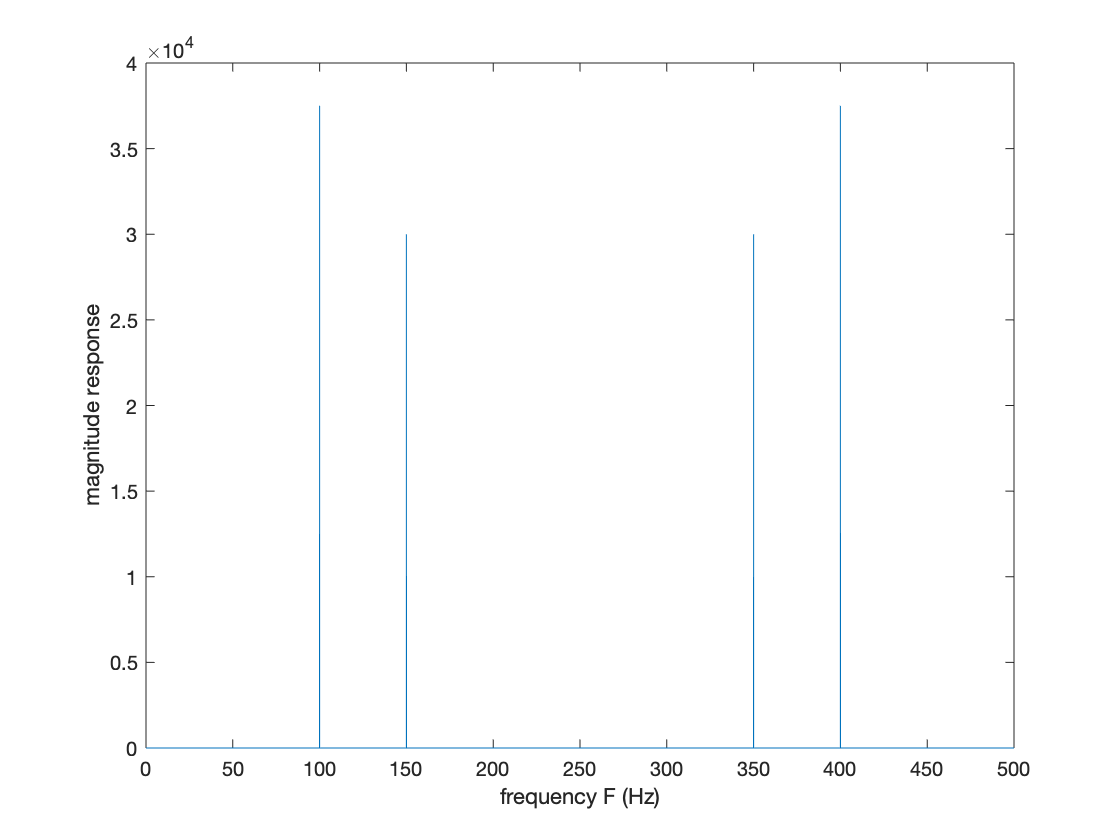

plot(f,abs(Y))
xlabel("frequency F (Hz)")
ylabel("magnitude response")

the original signal xc(t) can be recovered from x[n]，


$$\begin{array}{l}
F_s =500\;,\;\Omega_s =1000\pi \;,\Omega_H =300\pi \\
\Rightarrow \Omega_s >{2\Omega }_H 
\end{array}$$


There is no aliasing.

(c)

when Fs=100Hz


$$\Rightarrow X\left(e^{j\omega } \right)=100\sum_{k=-\infty }^{\infty } \left\lbrack 5\pi \left\lbrack \delta \left(100\omega -200\pi k-200\pi \right)+\delta \left(100\omega -200\pi k+200\pi \right)\right\rbrack +4i\pi \left\lbrack \delta \left(100\omega -200\pi k+300\pi \right)-\delta \left(100\omega -200\pi k-300\pi \right)\right\rbrack \right\rbrack$$


我將k=0和k=1的圖形分為X1和X2

dd為一個Dirac delta function，dd(0)=1

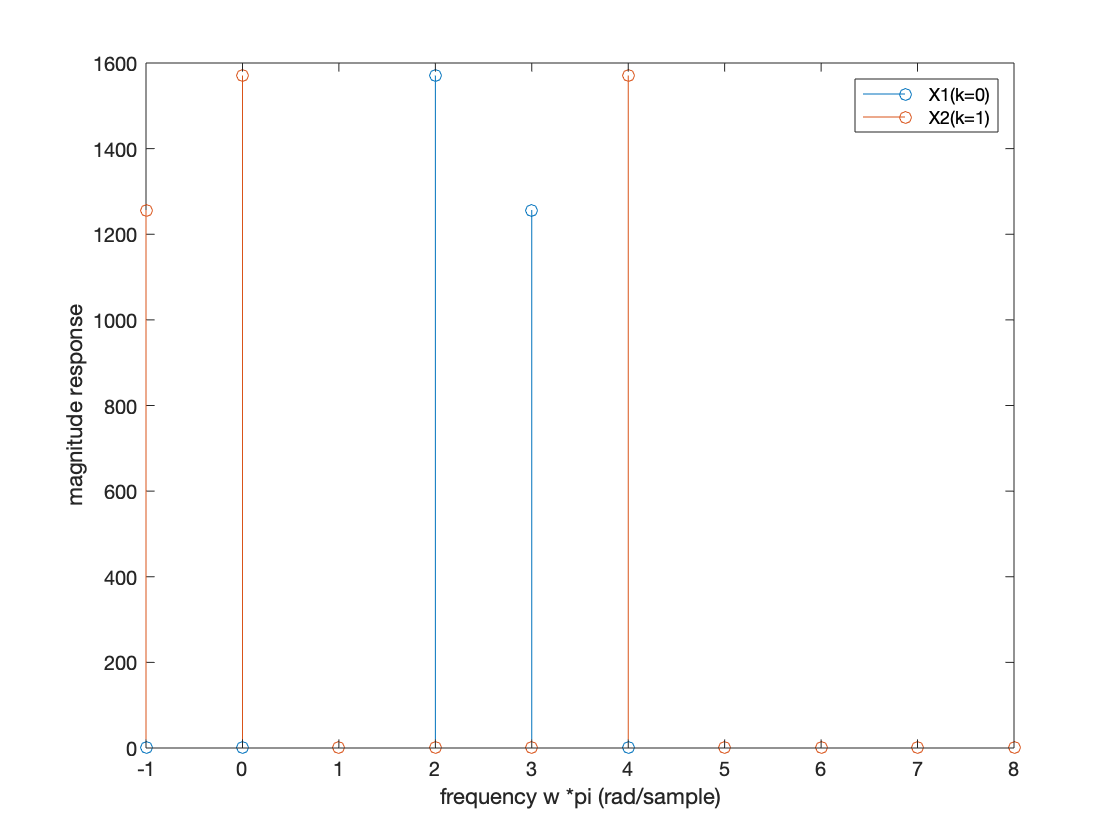

k=0;
for om=1:10
    X1(om)=5*pi*(dd(100*(om-2)*pi-200*pi*k-200*pi)+dd(100*(om-2)*pi-200*pi*k+200*pi))+4*pi*(dd(100*(om-2)*pi-200*pi*k+300*pi)-dd(100*(om-2)*pi-200*pi*k-300*pi));
end

k=1;
for om=1:10
    X2(om)=5*pi*(dd(100*(om-2)*pi-200*pi*k-200*pi)+dd(100*(om-2)*pi-200*pi*k+200*pi))+4*pi*(dd(100*(om-2)*pi-200*pi*k+300*pi)-dd(100*(om-2)*pi-200*pi*k-300*pi));
end
om=-1:1:8;
figure
stem(om,100*abs(X1))
hold on
stem(om,100*abs(X2))
hold off
legend("X1(k=0)","X2(k=1)")
xlabel("frequency w *pi (rad/sample)")
ylabel("magnitude response")

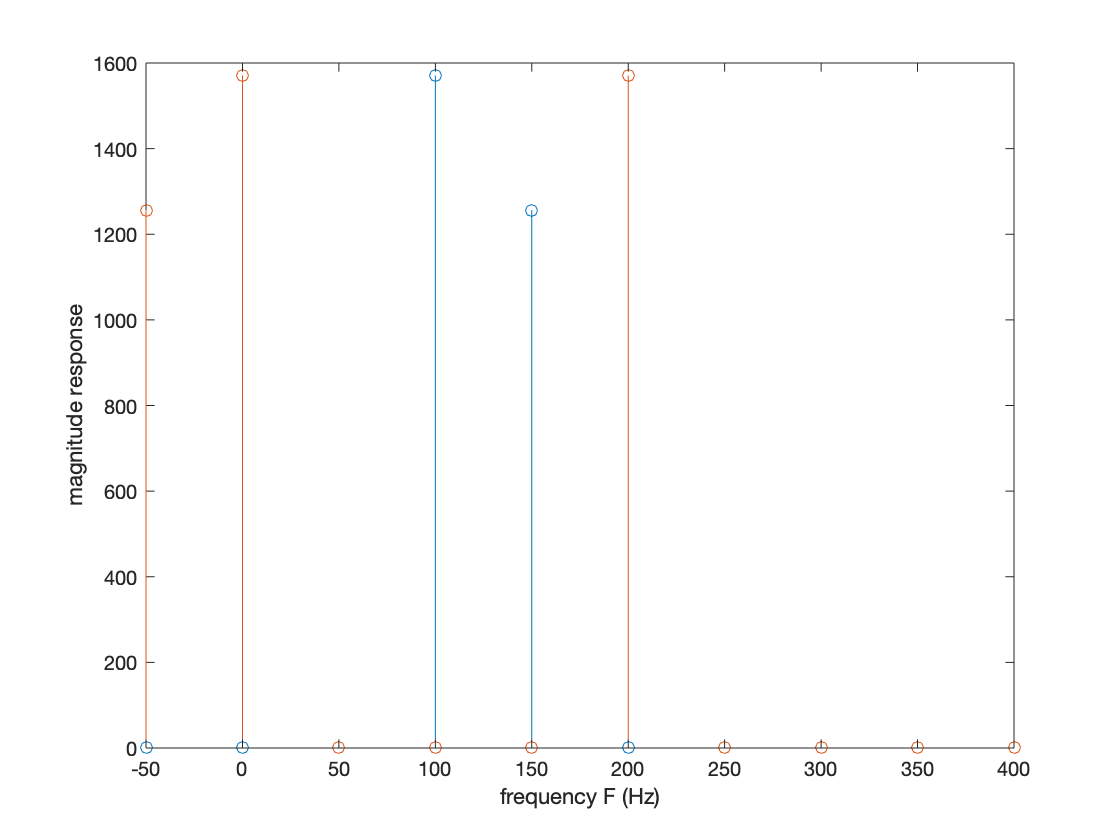

f=om*100/2;
figure
stem(f,100*abs(X1))
hold on
stem(f,100*abs(X2))
hold off
xlabel("frequency F (Hz)")
ylabel("magnitude response")

the original signal xc(t) can not be recovered from x[n]，


$$\begin{array}{l}
F_s =100\;,\;\Omega_s =200\pi \;,\Omega_H =300\pi \\
\Rightarrow \Omega_s <{2\Omega }_H 
\end{array}$$


sampling rate太小，從上圖可看出產生 aliasing.

(d)

sampling rate要大於2倍的Nyquist rate才能將signal還原，

$\textrm{Nyquist}\textrm{rate：}\Omega_H =300\pi \;,$所以sampling rate: $\Omega_s \;$要大於600$\pi$

$\Rightarrow Ｆ_s$要大於300Hz

由c小題可看出，當Fs<300Hz，畫出的頻譜會會出現aliasing